# Демодуляция ЧМ-сигналов

# Zero-Crossing Detector

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Zero-Crossing Detector

При частотной модуляции мгновенная частота несущей прямо пропорциональна информационному сообщению. Несущая представляет из себя гармоническое колебание с постоянной амплитудой. Значение несущей периодически изменяется свой знак, причем чем выше мгновенная частота, тем эти изменения чаще. Так как значения несущей являются непрерывной функцией от времени, то изменение знака равносильно пересечению несущей нулевого значения. Это наблюдение позволяет проводить оценку мгновенной частоты, что помощью подсчета количества пересечений через нулевое значение на заданном отрезке времени. Это далает название детектору: Zero-Crossing Detector. 

Демодулятор будет состоять из двух блоков: детектора пересечения нуля и фильтра нижних частот. Детектор пересечения нуля формирует импульсы в момент пересечения несущей нуля. В остальные моменты времени его выход равен нулю. Таким образом, сигнал на выходе детектора пересечения нуля представляет из себя последовательность коротких импульсов, частота следования которых прямо пропорциональна мгнавенной частоте несущей.

Чтобы оценить значение частоты несущей, достаточно подсчитать число импульсов, или, что тоже самое, интегрировать импульсный сигнал на заданном интервале времени. При этом ширина временнго интервала важна. Чем шире интервал, тем больше импульсов в него попадет и тем точнее будет оценка частоты. С другой стороны широкий интервал интеграирования не позволит увидель короткие изменения частоты несущей. 

Аппаратно интегрирование не определенном временном интервале можно приблиденно реализовать с помощью фильтра нижных частота. Интервал интегрирования будет соответствовать длительности импульсной характеристики фильтра. Выбирая полосу пропускания фильтра равной полосе информационного сообщения можно удалить все лишние частотные составляющие и восстановить сообщение.

Схема демодулятора на основе Zero-Crossing Detector имеет вид:

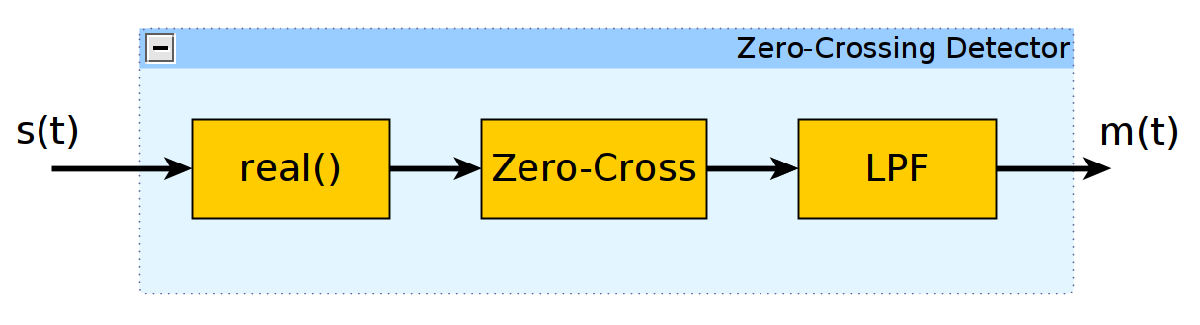

### 2. Демодуляция аудиосообщения

Рассмотрим демодуляцию аудиосообщения с помощью скрипта, реализующего Zero-Crossing Detector.

В файлах Audio_FM_ModIdx_*.wav записан частотно-модулированный сигнал с различными индексами модуляции. Частота несущей $f_s$ равна 100 kHz, а частота дискретизации $f_s$ = $441$ kHz. Считаем, что прием выполняется квадратурным способ, то есть сигнал имеет вид:


$$s\left(t\right)=A_с \cdot \exp^{j\cdot \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)} \ldotp$$


Выделяя из комплексного сигнала только действительную часть, получим:


$$\mathrm{real}\left\lbrace s\left(t\right)\right\rbrace =A_с \cdot \cos \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)\ldotp$$


Далее этот сигнал подается на детектор перехода через нулевое значение. Детектор реализован с помощью сравнения знаков текущего и предыдущего отсчетов сигнала. Сравнение знаков можно реализовать через вычисление знака произведения двух последовательных отсчетов. Если знак произведения меньше нуля, то текущий и предыдущий отсчет имеют разные знаки и был переход через нулевое значение.

Затем сигнал с выхода детектора перехода через нулевое значение подается на дециматор. В состав дециматора входит фильтр нижних частот, полоса пропускания которого равна полосе информационного сообщения. Таким образом одновременно выполняется фильтрация и децимация сигнала. После удаления постоянной составляющей получем восстановленное аудио сообщение.

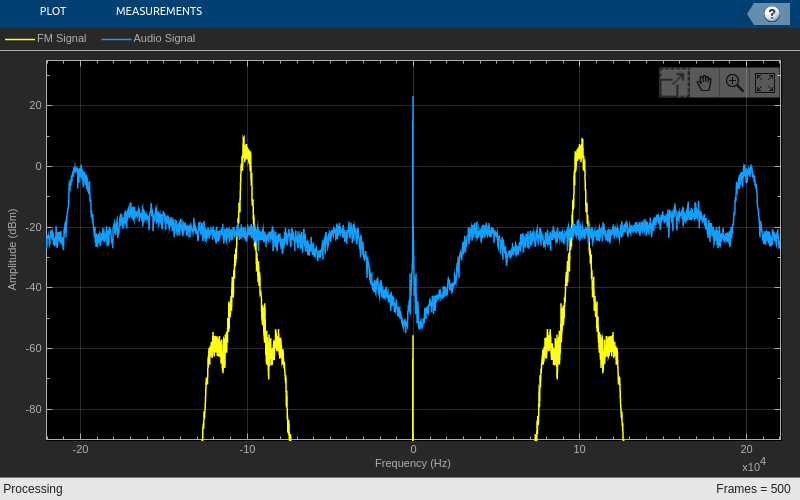

clc; clear; close all;

SignalFrameSize = 10000;          % количество отсчетов чм-сигнала, получаемых за один раз
FramesNumber = 500;               % число обрабатываемых пачек данных
AudioAmp = 1;                     % коэффициент усиления аудиосигнала
RateRatio = 10;                   % коэффициент увеличения частоты дискретизации
ModIndex = '02';   % индекс модуляции

% имя считываемого файла
SignalFileName = sprintf('wav/Audio_FM_ModIdx_%s.wav', ModIndex);

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    SignalFileName, ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% задержка 
DelayBlock = dsp.Delay;

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 30e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'FM Signal', 'Audio Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов ЧМ-сигнала и выделение синфазного канала
    FmSignal = AudioReader();
    FmSignal = FmSignal(:,1);
    
    % удаление постоянной составляющей
    FmSignal = FmSignal - mean(FmSignal);
 
    % поиск переходов через ноль
    FmSignalDelayed = DelayBlock(FmSignal);
    ZeroCross = (FmSignal .* FmSignalDelayed) <= 0;
    ZeroCross = double(ZeroCross);

    % понижение частоты дискретизации
    AudioSignal = DownSampler(ZeroCross);
    
    % убираем постоянную составляющую
    AudioSignal = AudioSignal - mean(AudioSignal);
    
    % формирование итогового сллбщения
    Message = [Message; AudioAmp * AudioSignal];

    % вычисление спектров
    SpectrumData = SpecEstimator([FmSignal ZeroCross]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

На спектрограмме желтым показан спектр частотно-модулированного сигнала, а синим - спектр на выходе детектора перехода через нулевое значение. Так как сигнал на выходе детектора импульсный, его спектр содержит сильные высокочастотные компаненты. 

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух можно понять, что аудиосообщение восстанавливается, однако сопровождается шумами. Одной из причин является заворот высокочастотных компонент относительно частоты Найквиста. Они попадают в полосу сообщения и их уже невозможно отфильтровать. Причем чем меньше индекс модуляции, тем сильнее шумы. Таким образом, Zero-Crossing Detector хуже работает при сигналах с низким индексом модуляции. 

Также отметим, что в данном демодуляторе подсчитывается число переходов через нулевой уровень. Чем больше таких переходов будет на интервале подстчета, тем точнее будет оценка мгновенной частоты. Количество переходов напрямую зависит от частоты несущей $f_с$. То есть при использовании Zero-Crossing Detector лучше, что бы частота несущей была выше.

### 3. Демодуляция FM-радио в Matlab

Ниже представлен скрипт, позволяющий прослушивать FM-радио с помощью RTL-SDR. Настройка на нужную радиостанцию выполняется с помощью переменной Fc, которая задает частоту несущей. Входной сигнал проходит через фильтр нижных частот для выделения нужной радиостанции. Далее сигнал с помощью умножения на комплексную экспоненту сдвигается на 200 kHz. Как упоминалось ранее, чтобы увеличить число переходов через нулевое значение, желательно, чтобы частота несущей была как можно выше. Частота сдвига в 200 kHz приемлемое решение при заданной частоте дискретизации. У сдвинутого по частоте сигнала выделяется действительная часть и она поступает на Zero-Crossing Detector. В заключение сигнал децимируется, у него удаляется постоянная составляющая и он подается на звуковую карту. 

clc; clear; close all;
addpath('matlab/demodulation');

Fc = 106.2e6;                % частота несущей в Hz
SignalFs = 1.2e6;            % частота дискретизации RTL-SDR
AudioFs = 48e3;              % частота дискретизации демодулированного аудиосигнала
SignalFrameSize = 512*25;    % количество отсчетов чм-сигнала, получаемых за один раз
FcShift = 200e3;             % частота сдвига после фильтрации
AudioAmp = 0.5;              % коэффициент усиления аудиосигнала

SDRRTL = comm.SDRRTLReceiver(...
    'RadioAddress', '0',...
    'CenterFrequency', Fc,...
    'EnableTunerAGC', true,...
    'SampleRate', SignalFs, ...
    'SamplesPerFrame', SignalFrameSize,...
    'OutputDataType', 'double' ...
);

% расчет коэффициентов и создание фильтра нижних частот
Fpass = 110e3;
Fstop = 160e3;
H = Audio_Lowpass_FIR_Coeff(SignalFs, Fpass, Fstop);
LowpassFIR = dsp.FIRFilter(H.Numerator);

% генератор для сдвига сигнала по частоте
Mixer = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', FcShift,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

% задержка на один отсчет
DelayBlock = dsp.Delay;

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 30e3, ...
    'StopbandAttenuation', 80, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'FM Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

% воспроизведение аудио сигнала
AudioSink = audioDeviceWriter(AudioFs);

% запуск симуляции
while(true)
    % получение отсчетов сигнала
    FmSignalData = SDRRTL();
    
    % вычисление спектров и вывод результатов на график
    SpectrumData = SpecEstimator(FmSignalData);
    Plotter(SpectrumData);
    
    % удаление постоянной составляющей
    FmSignalData = FmSignalData - mean(FmSignalData);
    
    % фильтрация
    FilteredData = LowpassFIR(FmSignalData);
    
    % сдвиг сигнала по частоте
    MixedData = FilteredData .* Mixer();
    
    % выделение действительной части сигнала и поиск переходов через ноль
    MixedData = real(MixedData);
    MixedDataDelayed = DelayBlock(MixedData);
    ZeroCross = (MixedData .* MixedDataDelayed) <= 0;
    ZeroCross = double(ZeroCross);
    
    % уменьшение частоты дискретизации
    AudioData = DownSampler(ZeroCross);
   
    % удаляем постоянную составляющую
    AudioData = AudioData - mean(AudioData);
    
    % проигрывание данных
    AudioSink(AudioData * AudioAmp);
  
end

### 4. Демодуляция FM-радио в Simulink

В файле FM_SDR_Receiver_Zero_Crossing.slx представлена Simulink-модель, позволяющая прослушивать FM-радио с помощью RTL-SDR. Все преобразования сигнала совпадают с теми, что ранее были описаны в Matlab скрипте.

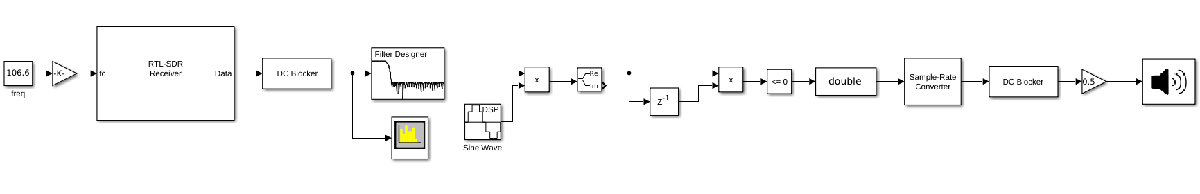

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR